# TP - Simulation des EDPs

14/03/23

Ce sont quoi les matrices A e B pour le chemin especifique ?

Ellles se deduisent a partir de l'equation discrete


$$B U^{n+1} = A  U^n + k F$$


$U^n$ contient les composantes des vecteurs u (solution du problème) en chaque point du domaine

On a toujours une distance h entre deux poits du mayage. Il faut contruir le mayage dans l'espace avec ça.

changer la condition initiale par :

$U_0 (x) = \frac{x}{2 \alpha} (1-x)$ de façon a avoi une fonction positive 

Comment a partir de cette equation discrete on peut definir le système ?

B c'est l'identité ?

**Comentaires du prof :**

soit on resoutdre le problême eu interieur du domaine ou au bord

solutions conues au bord 

conditionlimites et on resoudre le sisteme dans ces conditions limites

A =  A1 + A2

programmer une matrix Nx fois Nx comme la matrix C donné par l'ennoncé

U doit avor les valeurs tès proches de la solution initiale ici : $B U^1 = A U^0 + kF$ (première pas) (F = 0 dans la programation (dans le compte rendu on dit que c'est un première F quelconque))

São todos aproximações do primeiro termo da equação dada no inínio do arquivo.

Le matrix A e B sont des moyennes ponderées 

trouver la matriz B pour le chemin explicide pour le R chemin (Kelt Nickelson)

ligne x = xC n'est pas necéssaire

on peut faire la question 2 (plus difficile, assez technique) ou regarder la précision de l'ordre du chemin. On peut choisir. Mais ça serait bien de faire les deux pour garantir une bonne note.

clear all; close all; clc;

L = 1;
alpha = 1;

% on prend tout dabord un valeur petit que peuve etre modifié aprés
Nx = 9; % nombre de poits de discrétisation du domaine

h = 1/(Nx + 1);


aux = [-1 2 -1];
C = [[2 -1],  zeros(1, Nx - 2)];
for i = [0:Nx-3]
    C = [C ; [zeros(1, i) , aux , zeros(1, Nx - 3 - i)]];
end
C = [C; [zeros(1, Nx - 2), [-1 2]] ]

C =      2    -1     0     0     0     0     0     0     0
    -1     2    -1     0     0     0     0     0     0
     0    -1     2    -1     0     0     0     0     0
     0     0    -1     2    -1     0     0     0     0
     0     0     0    -1     2    -1     0     0     0
     0     0     0     0    -1     2    -1     0     0
     0     0     0     0     0    -1     2    -1     0
     0     0     0     0     0     0    -1     2    -1
     0     0     0     0     0     0     0    -1     2


B = eye(Nx)

B =      1     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0
     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     1



$$\alpha \cdot \frac{k}{h^2} < \frac{1}{2}$$


k = 0.5*((h^2)/alpha)

k = 0.0050

A = eye(Nx) - ((k*alpha)/(h^2))*C

A =          0    0.5000         0         0         0         0         0         0         0
    0.5000         0    0.5000         0         0         0         0         0         0
         0    0.5000         0    0.5000         0         0         0         0         0
         0         0    0.5000         0    0.5000         0         0         0         0
         0         0         0    0.5000         0    0.5000         0         0         0
         0         0         0         0    0.5000         0    0.5000         0         0
         0         0         0         0         0    0.5000         0    0.5000         0
         0         0         0         0         0         0    0.5000         0    0.5000
         0         0         0         0         0         0         0    0.5000         0



x = h*[1:Nx]';

U0 = x/(2*alpha).*(1-x);

F = 0

F = 0

%U1 = B*(A*U0 + k*F)
%U1 = A*U0

Usol = [U0]

Usol =     0.0450
    0.0800
    0.1050
    0.1200
    0.1250
    0.1200
    0.1050
    0.0800
    0.0450


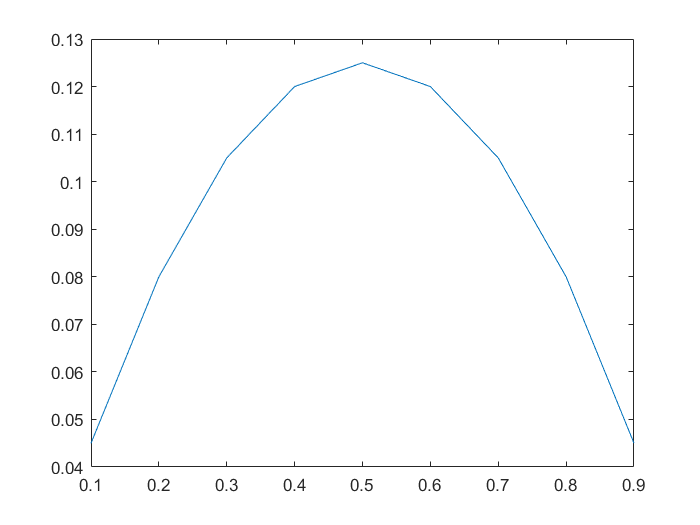

plot(x, U0)

n = 10

n = 10

for n = [1:n]
    Usol = [Usol , B*(A*Usol(:,n) + k*F)];
end

disp(Usol)

  Columns 1 through 8

    0.0450    0.0400    0.0375    0.0350    0.0331    0.0313    0.0297    0.0281
    0.0800    0.0750    0.0700    0.0663    0.0625    0.0594    0.0562    0.0535
    0.1050    0.1000    0.0950    0.0900    0.0856    0.0812    0.0773    0.0734
    0.1200    0.1150    0.1100    0.1050    0.1000    0.0953    0.0906    0.0863
    0.1250    0.1200    0.1150    0.1100    0.1050    0.1000    0.0953    0.0906
    0.1200    0.1150    0.1100    0.1050    0.1000    0.0953    0.0906    0.0863
    0.1050    0.1000    0.0950    0.0900    0.0856    0.0812    0.0773    0.0734
    0.0800    0.0750    0.0700    0.0662    0.0625    0.0594    0.0562    0.0535
    0.0450    0.0400    0.0375    0.0350    0.0331    0.0313    0.0297    0.0281

  Columns 9 through 11

    0.0268    0.0254    0.0242
    0.0508    0.0483    0.0459
    0.0699    0.0664    0.0632
    0.0820    0.0781    0.0742
    0.0863    0.0820    0.0781
    0.0820    0.0781    0.0742
    0.0699    0.0664    0.0632
    0.

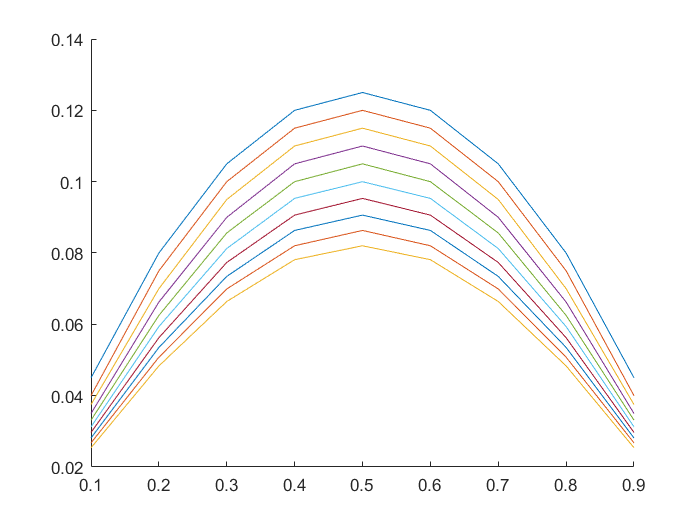

figure();
hold on
for i = [1:n]
    plot(x, Usol(:,i))
end

### Schema Implicite

j -> point (x,j) du mayage dans l'espace

solution au bord -> 

como eu modifico a matriz A para ter a solução vermelha que ele passou no quadro no canto fireito inferior ?

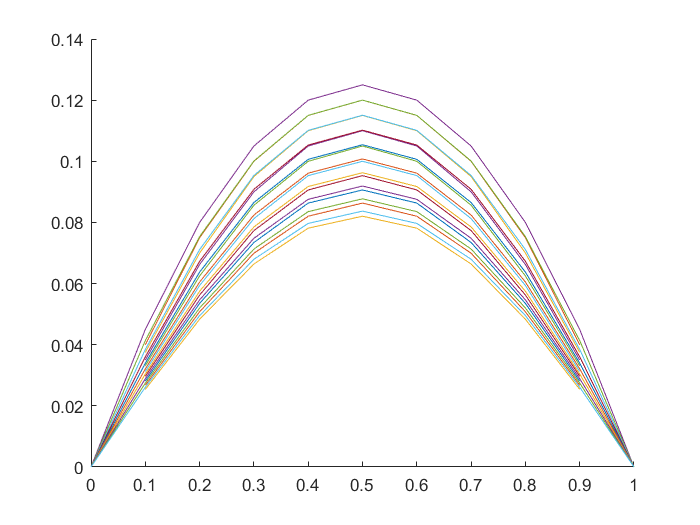

Bimp = eye(Nx) + (k/(h^2))*C;
Aimp = eye(Nx);

U0 = x.*(1-x)/(2*alpha);
U1 = U0;

n = 10;
hold on
for i = [1:n]
    plot([0; x; 1], [0; U1; 0]);
    U1 = inv(Bimp)*Aimp*U0;
    U0 = U1;
end